## Parámetros

rotacion = pi/4; %pi/4
factor = 4/3; %1 a 4/3
lmin = 15;
es = 3.5;
hojas = 4;
n = 3000;

lcx = 20;
lcy = 9;

q10 = 0*(pi/180);
q20 = 165*(pi/180);

%Valores iniciales de los angulos
q10i = q10;
q20i = q20;

l1 = 19;
l2 = 18;

## Trébol estilizado

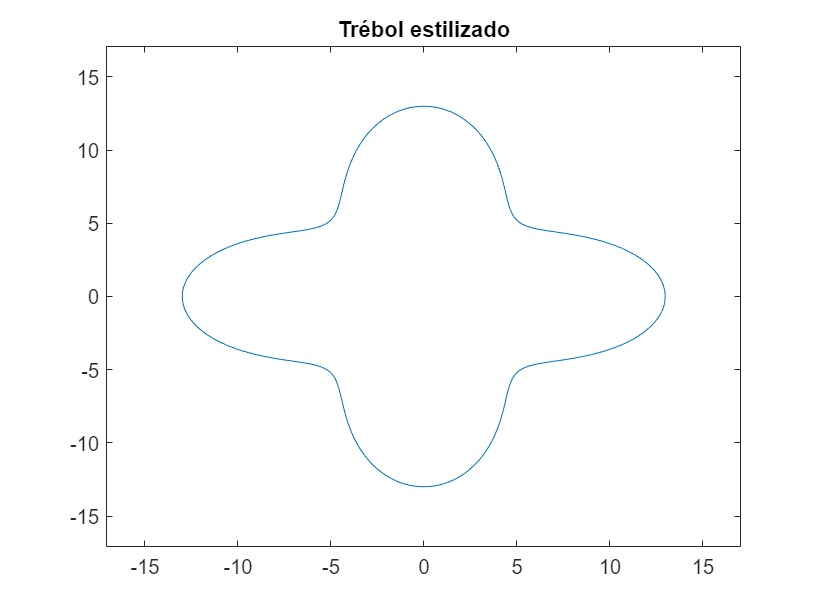

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

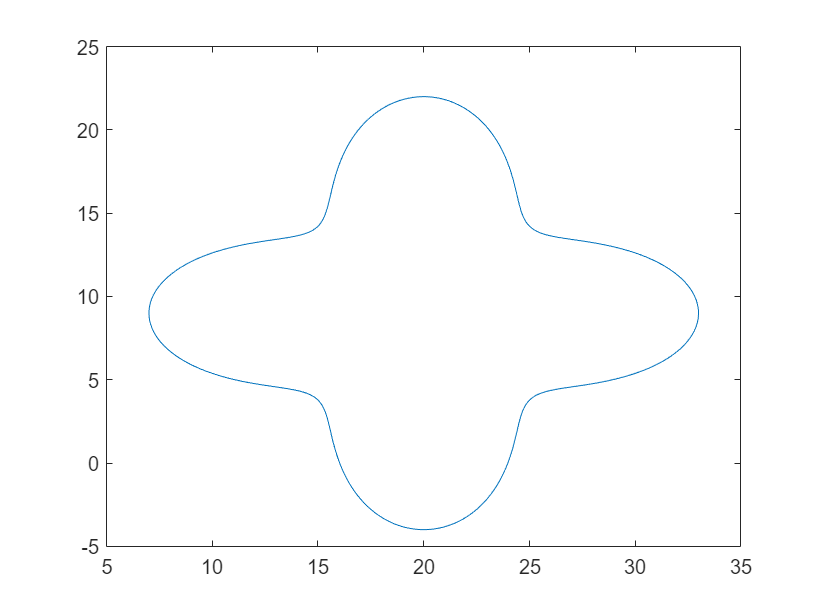

[x,y]=Totrigen(lcx,lcy,theta,r);
plot(x,y)

## Cinemática inversa

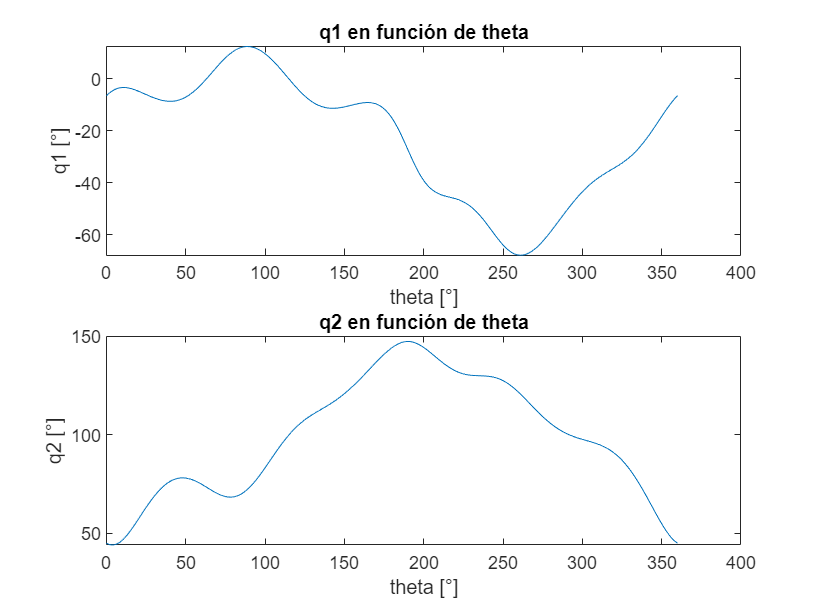

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')

## Trayectoria de acercamiento

[x20, y20] = Cdirecta(l1,l2,q10i,q20i); %Posición inicial extremo distal
[distPoint] = sqrt((x-x20).^2+(y-y20).^2);
minimo = min(distPoint)

minimo = 6.4577

pos = find(distPoint==minimo,1)

pos = 1553

distPoint(pos);
%pos = (n/2) + 1; %Aprox en pi
[x2f, y2f] = Totrigen(lcx,lcy,theta(pos),r(pos));
Xaprox = linspace(x20,x2f,100);
Yaprox = linspace(y20,y2f,100);
% figure()
% hold on
% plot(Xaprox,Yaprox)
% plot(x,y)
% hold off

## Perfil trapezoidal Acercamiento

deltaX = x2f-x20

deltaX = 5.7469

deltaY = y2f-y20

deltaY = 2.9454

t = 5; %s
t1 = t/3; %Perfiles con tiempos iguales
VcX = (0.5*deltaX)/t1;
VcY = (0.5*deltaY)/t1;

t = linspace(0,t,100);

mX = VcX/t1;
mY = VcY/t1;
Vx = mX*t-mX*(t-t1).*(t>=t1)-mX*(t-2*t1).*(t>=2*t1)

Vx =          0    0.0522    0.1045    0.1567    0.2090    0.2612    0.3135    0.3657    0.4180    0.4702    0.5224    0.5747    0.6269    0.6792    0.7314    0.7837    0.8359    0.8882    0.9404    0.9927    1.0449    1.0971    1.1494    1.2016    1.2539    1.3061    1.3584    1.4106    1.4629    1.5151    1.5673    1.6196    1.6718    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241    1.7241


Vy = mY*t-mY*(t-t1).*(t>=t1)-mY*(t-2*t1).*(t>=2*t1)

Vy =          0    0.0268    0.0536    0.0803    0.1071    0.1339    0.1607    0.1874    0.2142    0.2410    0.2678    0.2945    0.3213    0.3481    0.3749    0.4016    0.4284    0.4552    0.4820    0.5087    0.5355    0.5623    0.5891    0.6158    0.6426    0.6694    0.6962    0.7229    0.7497    0.7765    0.8033    0.8301    0.8568    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836    0.8836


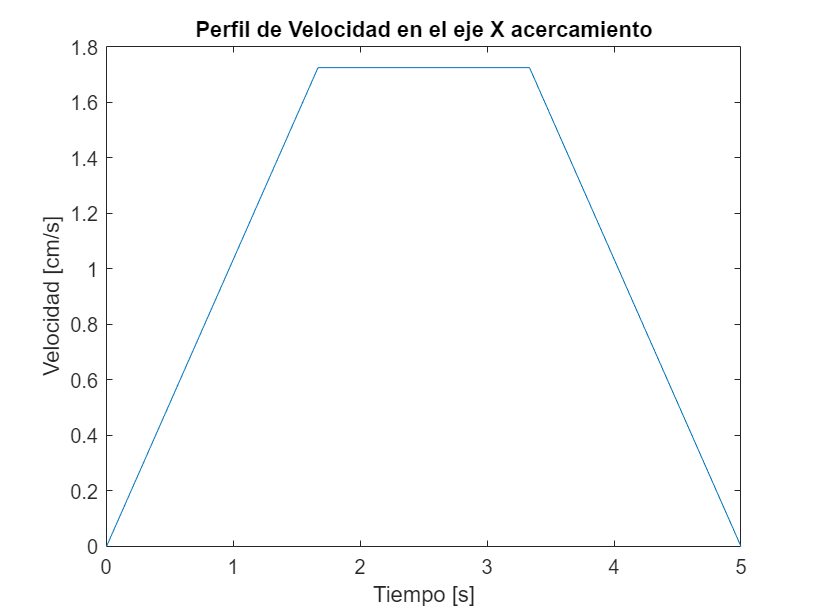


Px = 0.5*mX*t.^2-0.5*mX*((t-t1).^2).*(t>=t1)-0.5*mX*((t-2*t1).^2).*(t>=2*t1)+x20;

Py = 0.5*mY*t.^2-0.5*mY*((t-t1).^2).*(t>=t1)-0.5*mY*((t-2*t1).^2).*(t>=2*t1)+y20;

figure()
plot(t,Vx)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje X acercamiento')

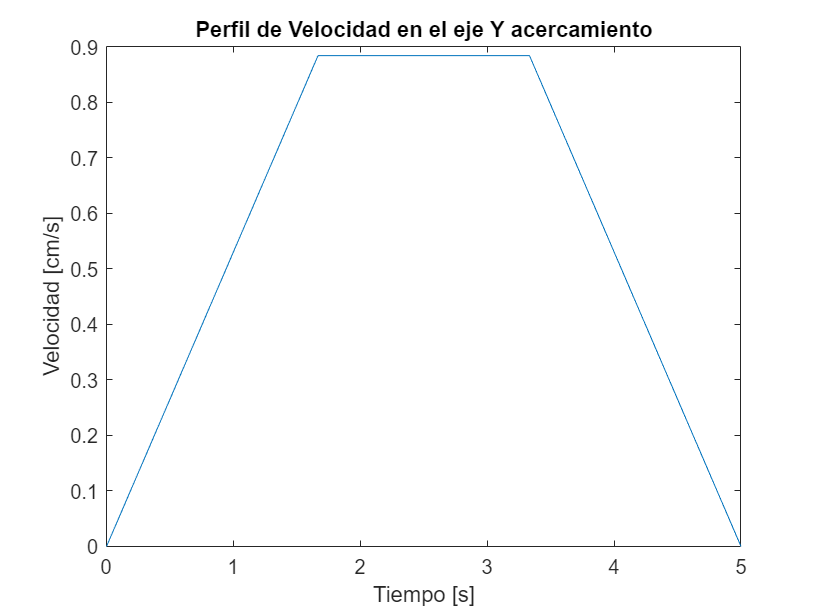


figure()
plot(t,Vy)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje Y acercamiento')

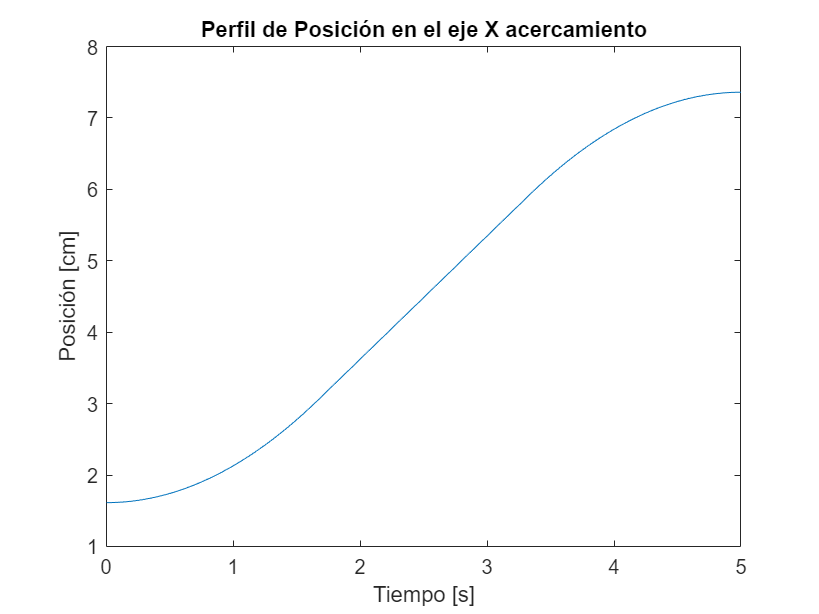


figure()
plot(t,Px)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje X acercamiento')

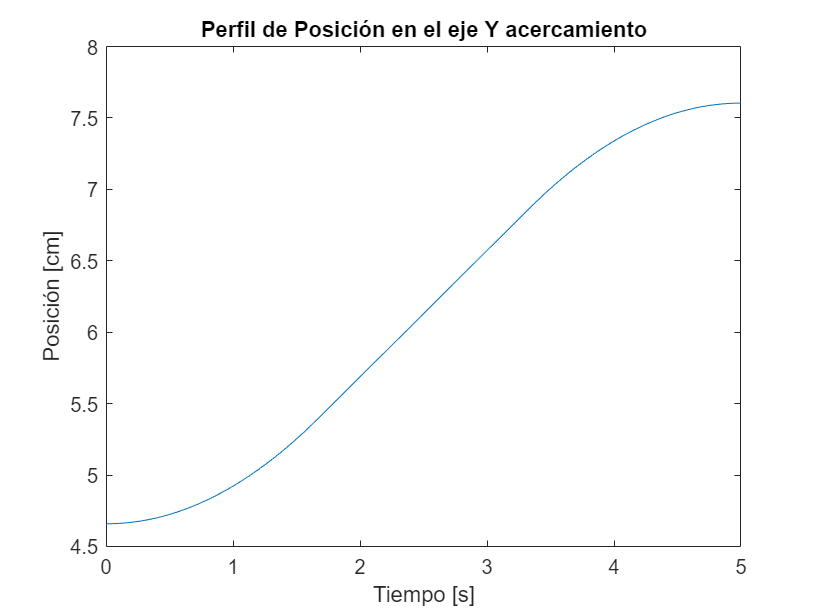


figure()
plot(t,Py)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje Y acercamiento')

## Visualización

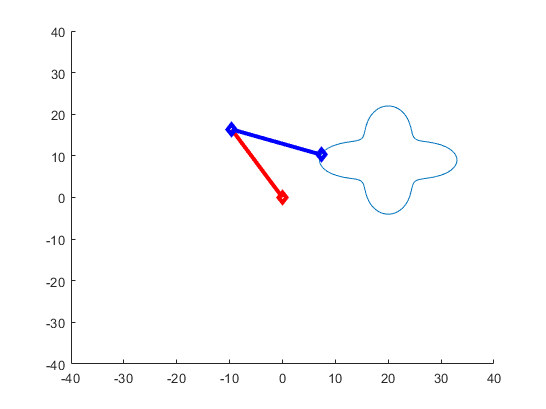

%Vectores de la posición distal del mecanismo en todo momento
XTotal = [Xaprox, x(1,pos:end), x(1,1:pos-1)];
YTotal = [Yaprox, y(1,pos:end), y(1,1:pos-1)];

%Cinematica inversa de todo el movimiento
q1 = zeros(1,length(XTotal));
q2 = zeros(1,length(YTotal));
figure(); %creamos la figura para visualizar
for i = 1:length(x)
    %Cinematica inversa
    [q1(i), q2(i)] = Cinversa(l1,l2,XTotal(i),YTotal(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
    %Gráfica
    cla;    %clear axes
    hold on
    plot(x,y);%Trebol base
    %Primer eslabon
    x1 = l1*cos(q1(i));
    y1 = l1*sin(q1(i));
    %Segundo eslabon
    x2 = XTotal(i);
    y2 = YTotal(i);
    plot([0 x1],[0 y1],'rd-','LineWidth',3)
    plot([x1 x2],[y1 y2],'bd-','LineWidth',3)
    pause(0.00001);
    xlim([-40 40]);
    ylim([-40 40]);
end


% figure()
% hold on
% x1 = l1*cos(q1(end));
%     y1 = l1*sin(q1(end));
%     %Segundo eslabon
%     x2 = XTotal(end);
%     y2 = YTotal(end);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)